# Example 7.10: Assessing the Quality of a Stochastic Solution

Note: this script reproduces Example 7.10 (Section 7.6.6) of **Statistics for Chemical Engineers**: sample average approximation (SAA) with different sample sizes S, with upper and lower bounds. Victor Z UW-Madison, 2023 sample average approximation example

clc; clear all; close all hidden; rng(0);
format compact;

## Setup

general info

 u0 = 1;     % initial guess
alp = 0.05;  % alpha corresponding to confidence level 0.95
  z = norminv(1-alp/2,0,1); % quantile Q(1-alp/2) for N(0,1)
  B = 10;    % batch size for bounds
opt = optimoptions('fmincon','Display','none','Algorithm','sqp');

## Solutions for different S

try different sample sizes

S=[1 10 50 100 500 1000 5000 10000];
S=round(S);

for k=1:length(S)
    

## generate scenarios for random variable

 mu = 1;
sig = 10;
  X = normrnd(mu,sig,S(k),1);

## get candidate solution

uc(k) = fmincon(@myfun,u0,[],[],[],[],[],[],[],opt,X);
 E(k) = myfun(uc(k),X);

## obtain upper bound

Eub=[];
for j=1:B
  Xs = normrnd(mu,sig,S(k),1);
  Eub(j) = myfun(uc(k),Xs);    
end
mub(k) = mean(Eub);
sub(k) = std(Eub);
lub(k) = z*sub(k)/sqrt(B);

## obtain lower bound

ulb=[]; Elb=[];
for j=1:B
  Xs = normrnd(mu,sig,S(k),1);
  ulb(j) = fmincon(@myfun,u0,[],[],[],[],[],[],[],opt,Xs);
  Elb(j) = myfun(ulb(j),Xs);  
end

% lower bound of optimal objective E
 mlb(k) = mean(Elb);
 slb(k) = std(Elb);
 llb(k) = z*slb(k)/sqrt(B);

% lower bound of optimal solution u
mulb(k) = mean(ulb);
sulb(k) = std(ulb);
lulb(k) = z*sulb(k)/sqrt(B);

end

## Gap and confidence of the bounds

analyze results

% gap
gap = [S' abs(mub-mlb)']

gap = 1.0e+04 *

    0.0001    0.0318
    0.0010    0.0060
    0.0050    0.0011
    0.0100    0.0001
    0.0500    0.0005
    0.1000    0.0004
    0.5000    0.0002
    1.0000    0.0000



% confidence of lower bound
conflb = [S' mlb' llb']

conflb = 1.0e+04 *

    0.0001    0.0000    0.0000
    0.0010    0.0072    0.0023
    0.0050    0.0103    0.0006
    0.0100    0.0099    0.0012
    0.0500    0.0094    0.0003
    0.1000    0.0096    0.0004
    0.5000    0.0101    0.0001
    1.0000    0.0100    0.0001



% confidence of solution u
confulb = [S' mulb' lulb']

confulb = 1.0e+04 *

    0.0001    0.0010    0.0006
    0.0010    0.0000    0.0002
    0.0050    0.0002    0.0001
    0.0100    0.0001    0.0000
    0.0500    0.0001    0.0000
    0.1000    0.0001    0.0000
    0.5000    0.0001    0.0000
    1.0000    0.0001    0.0000


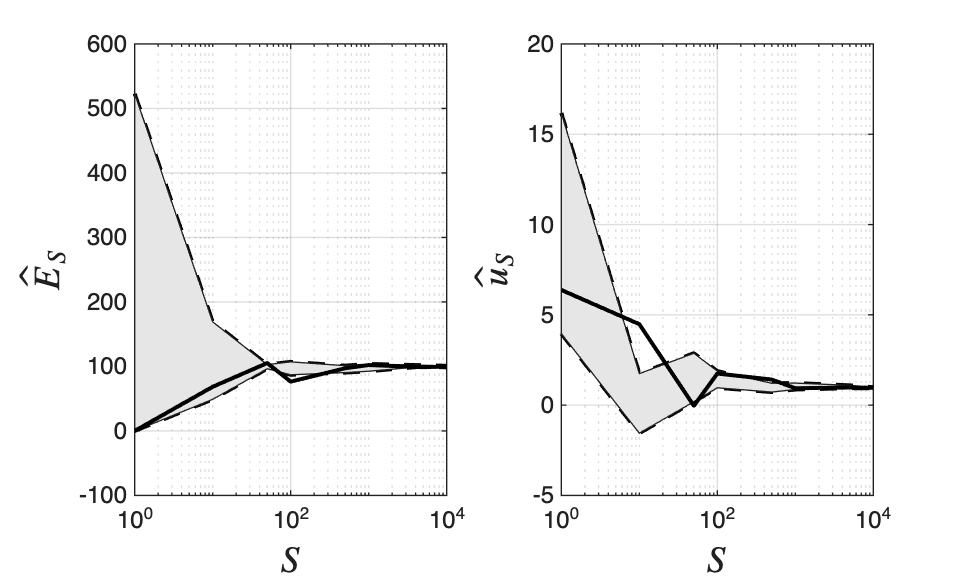


% visualize
figure(1)
subplot(1,2,1)
semilogx(S,mub+lub,'black--','LineWidth',1.5)
hold on; grid on;
semilogx(S,mlb-llb,'black--','LineWidth',1.5)
S2 = [S, fliplr(S)];
inBetween = [mlb-llb, fliplr(mub+lub)];
fill(S2, inBetween,[0.9 0.9 0.9]);
semilogx(S,E,'black','LineWidth',1.5)
xlabel('$S$','Interpreter','latex','FontSize',14)
ylabel('$\hat{E}_S$','Interpreter','latex','FontSize',14)

figure(1)
subplot(1,2,2)
semilogx(S,mulb-lulb,'black--','LineWidth',1.5)
hold on; grid on
semilogx(S,mulb+lulb,'black--','LineWidth',1.5)
S2 = [S, fliplr(S)];
inBetween = [mulb-lulb, fliplr(mulb+lulb)];
fill(S2, inBetween,[0.9 0.9 0.9]);
semilogx(S,uc,'black','LineWidth',1.5)
xlabel('$S$','Interpreter','latex','FontSize',14)
ylabel('$\hat{u}_S$','Interpreter','latex','FontSize',14)
print -depsc ch7_saa_analysis.eps

## define function to minimize

function E=myfun(u,X)
 
phi = (u-X).^2; % - u*exp(0.5*X);
  E = mean(phi);
 
end

## Note

As in the book, the gap between the bounds shrinks quickly as S grows (from 318 for S = 1 to about 1 for large S): the SAA solution converges quickly.